# SASNE running example

data = readmatrix('data/imbalanced_test.txt');

[sasne_out,Z] = SASNE(data);

constructing graph...


W =    (5,1)       0.3414
  (14,1)       0.5682
  (17,1)       0.5785
  (30,1)       0.5383
  (38,1)       0.5030
   (5,2)       0.6807
  (17,2)       0.6901
  (18,2)       0.7888
  (22,2)       0.7140
  (28,2)       0.5635
  (29,2)       0.6289
  (33,2)       0.4801
  (34,2)       0.7317
  (38,2)       0.6082
  (16,3)       0.2363
  (20,3)       0.3937
  (23,3)       0.6161
  (24,3)       0.4845
 (138,3)       0.6285
 (206,3)       0.4182
   (6,4)       0.5675
  (42,4)       0.4290
  (78,4)       0.6808
 (339,4)       0.4312
 (356,4)       0.4038
   (1,5)       0.3414
   (2,5)       0.6807
   (8,5)       0.6997
  (12,5)       0.7347
  (18,5)       0.7883
  (27,5)       0.5928
  (30,5)       0.7399
  (41,5)       0.4541
  (50,5)       0.4689
   (4,6)       0.5675
  (10,6)       0.6326
  (11,6)       0.5098
  (42,6)       0.4656
  (46,6)       0.5963
  (78,6)       0.5897
  (15,7)       0.8686
  (19,7)       0.5210
  (22,7)       0.6394
  (31,7)       0.9575
  (34,7)       0.8189
  (36,

Elapsed time is 0.128905 seconds.
computing graph distance...
Elapsed time is 0.140049 seconds.
computing tsne embedding...
Elapsed time is 1.590352 seconds.
Total running time 1.8628 seconds


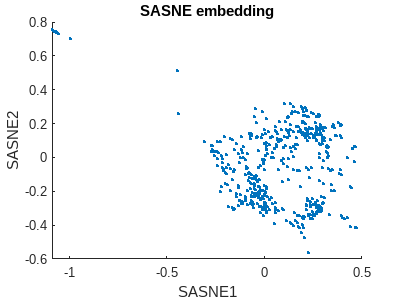

figure
scatter(sasne_out(:,1),sasne_out(:,2),5,'filled')
title('SASNE embedding')
xlabel('SASNE1')
ylabel('SASNE2')

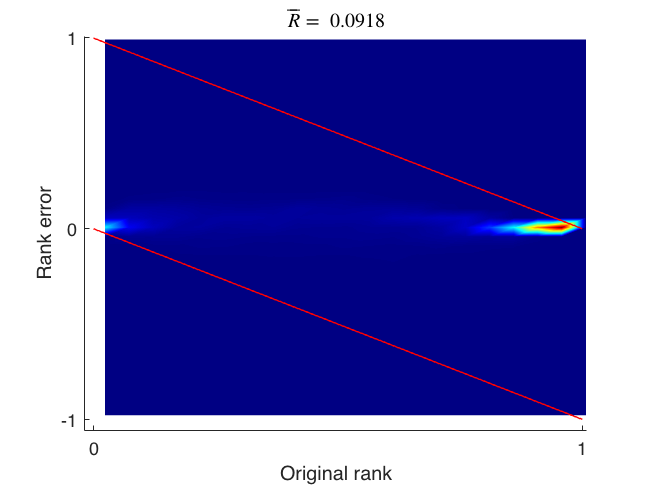

D_original = pdist(Z,'euclidean');
D_sasne = pdist(sasne_out,'euclidean');
RRP(D_original,D_sasne);

clear D_original D_sasne ans